originalImg = imread('PES_NOTES/SEM_5/DIP/img_1.png');
img = originalImg;
if size(img, 3) == 3
    img = rgb2gray(img);
end
img = im2double(img);
img = imgaussfilt(img, 0.8);
background = imgaussfilt(img, 50);
img = img - background + 0.5;
img(img < 0) = 0;
img(img > 1) = 1;
img = imadjust(img, stretchlim(img, [0.001 0.999]), []);
img = adapthisteq(img, 'ClipLimit', 0.01, 'NumTiles', [16 16]);
img = imsharpen(img, 'Radius', 1.5, 'Amount', 1.2);
cleanImage = imbinarize(img, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.4);
cleanImage = bwareaopen(cleanImage, 8);
se = strel('disk', 1);
cleanImage = imdilate(cleanImage, se);
if mean(cleanImage(:)) < 0.5
    cleanImage = ~cleanImage;
end
fprintf('\n=== Performing OCR on Cleaned Document ===\n');


=== Performing OCR on Cleaned Document ===


ocrResults = ocr(cleanImage);
extractedText = ocrResults.Text;
avgConfidence = mean(ocrResults.CharacterConfidences);
fprintf('Average OCR Confidence: %.2f%%\n', avgConfidence);

Average OCR Confidence: NaN%


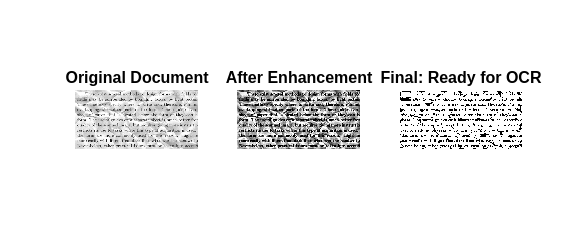

figure('Name', 'Document Cleaning for OCR', 'Position', [50 50 1400 600]);
subplot(1, 3, 1);
imshow(originalImg);
title('Original Document', 'FontSize', 12, 'FontWeight', 'bold');
subplot(1, 3, 2);
imshow(img);
title('After Enhancement', 'FontSize', 12, 'FontWeight', 'bold');
subplot(1, 3, 3);
imshow(cleanImage);
title('Final: Ready for OCR', 'FontSize', 12, 'FontWeight', 'bold');

figure('Name', 'Extracted Text', 'Position', [100 100 800 600]);
annotation('textbox', [0.1 0.1 0.8 0.8], 'String', extractedText, ...
    'FontSize', 11, 'EdgeColor', 'black', 'BackgroundColor', 'white', ...
    'Interpreter', 'none', 'VerticalAlignment', 'top');
fprintf('\n=== Processing Complete ===\n');


=== Processing Complete ===


fprintf('Text extracted and displayed in separate figure.\n');

Text extracted and displayed in separate figure.


fprintf('Black text on white background, noise removed.\n\n');

Black text on white background, noise removed.



fprintf('=== EXTRACTED TEXT ===\n');

=== EXTRACTED TEXT ===


fprintf('%s\n', extractedText);

PB.  There exist seypeal methods jo degign Forms x fields BW
fmy be surrounded. Bounding boasby Ilghit rectall
“These amet! MEd ecily where to mrite and, therefofe, minis
elappiig witha ark of the foun Thess gies
sheomal paper that is Rated below the form, of they can b
x. The wee guides dg x Swaratr Mists Tuuch bettertror
quality of the scanned imag¥, but reqiiees giving more str
restricts its ume tdtasks where thie type Bf acqhuitipn isu
sth form are more’ commonf¥ used for ME Yeaso® Light-re
more easily with lye Beanalerk lines the pai

Nevertheless, other practical -igsucs must Ge ta




fprintf('======================\n\n');